## Modelo de previsão

#### Limpa a memória e define variaveis de configuração do sistema

clear all; clc;

train   = 0.6;
eps     = 0.005;
funcQtd = [7, 6, 5, 4, 8, 6, 4];
alph    = 0.01; 
epoch   = 40;

#### Importa dados do sistema

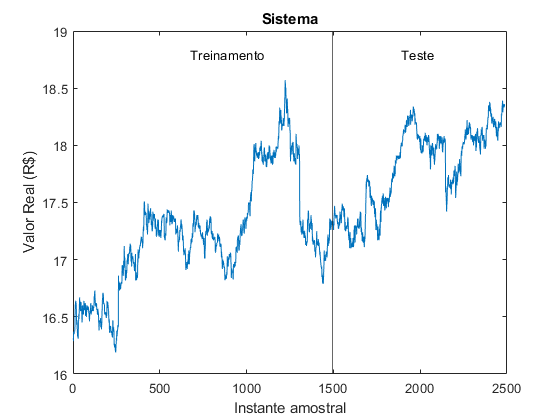

path = "C:\Users\gabri\OneDrive\Área de Trabalho\scholl\Economia\datas\";
x = readmatrix(path+'inputs.xls'); 
y = readmatrix(path+'inputs.xls');
[lineQtd, colQtd] = size(x);

x = x(2:lineQtd,:);    y = y(2:lineQtd);
st = lineQtd - round(lineQtd*(1-train));
lineQtd = lineQtd - 1;

clf; figure(1); 
plot(y); title("Sistema");  xline(st);
text(st/2*0.9, 18.8, "Treinamento");
text((st+ (lineQtd-st)/2)*0.95, 18.8, "Teste");
xlabel("Instante amostral");
ylabel("Valor Real (R$)")

#### Define as funções e os dados de entrada

funcDef = zeros(length(funcQtd),3);
for i = 1:1:length(funcQtd)
    funcDef(i,1) = funcQtd(i);
end

funcQtdS = sum(funcQtd);

funcs = [];
for i = 1:1:colQtd
    funcDef(i,2) = min(x(:,i));
    funcDef(i,3) = max(x(:,i));
    funcs = [funcs triComp(funcDef(i,:))];
end

#### Plota as funções de transferências definidas

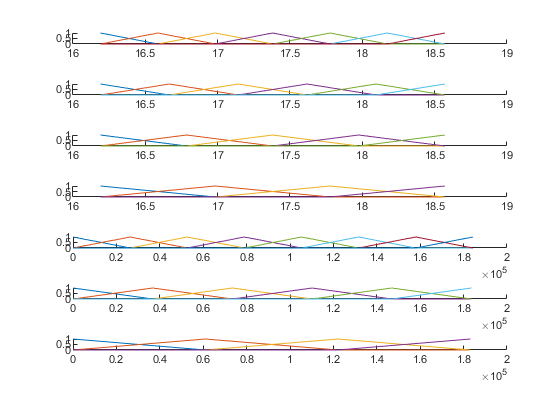

cont=0; clf; figure(2);
for i = 1:1:colQtd
    subplot(colQtd,1,i); hold on;
    for j =1:1:funcDef(i,1)
        cont = cont + 1;
        fplot(@(x)funcs{cont}(x), [funcDef(i,2), funcDef(i,3)]); 
    end
    hold off; 
end

#### Treinamento do Modelo

define os pesos iniciais e variáveis auxiliares

w = linspace(0.3,0.5,funcQtdS);
outs = linspace(1,1,colQtd); 
pertinence = linspace(1,1,funcQtdS); errFun = []; errInt = [];

Inicia o treinamento do modelo com '%'1 - train  do conjunto completo

for HH=1:1:epoch
    for i = 1:1:lineQtd*(train)               % Caminha por todo conjunto de trienamento       
        cont = 1; 
        for j = 1:1:colQtd                    % Passa por todas as entradas da amostra
            start = cont;  
            for k = 1:1:funcDef(j,1)          % Verifica a entrada em cada função
                pertinence(cont) = funcs{cont}(x(i,j));
                cont = cont+1;
            end
            outs(j) = neuron(pertinence(start:cont-1), w(start:cont-1));
        end
        err = sum(outs) - y(i);
        errInt = [errInt err];
        if abs(err) > eps
           alph = 1 / sum(pertinence.^2);
           for j = 1:1:length(w)
               w(j) = w(j) - alph*pertinence(j)*err;
           end
        end
    end
    errFun = [errFun mean(errInt)]; errInt = [];
end

Define o modelo com os parametros obtidos no treinamento

model = @(xTest) NFN(xTest, w, funcs, funcDef);

#### Executa o modelo nos dados de Teste

result = linspace(0, 0, lineQtd - st);        
yTest = y(st:lineQtd)';
xTest = x(st:lineQtd,:);
yTest = y';
xTest = x;


for i = 1:1:length(yTest)               % Caminha por todo conjunto de dados       
    result(i) = model(xTest(i,:));
end

Plota os resultados obtidos com os esperados

xb = 1:1:lineQtd-st+1; 
xb = 1:1:length(yTest);  
errVec = yTest' - result;
std(errVec)                % Desvio padrão da previsão

ans = 0.0171

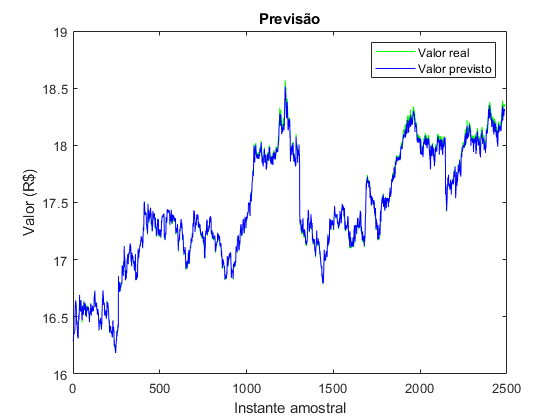

clf; figure(3); 
plot(xb, yTest', '-g', xb, result, '-b'); title("Previsão");
legend("Valor real","Valor previsto");
xlabel("Instante amostral");
ylabel("Valor (R$)")

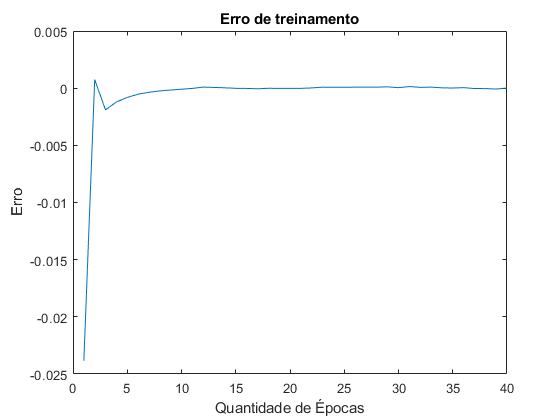

figure(4); 
plot(errFun); title("Erro de treinamento");
xlabel("Quantidade de Épocas");
ylabel("Erro");

mean(yTest' - result)

ans = 0.0062


for i = 1:1:length(yTest)
    yTest(i) = round(yTest(i),2);
    result(i) = round(result(i),2);
end

response = [yTest, result'];
response = ["real", "previsto"; response];
path = "C:\Users\gabri\OneDrive\Área de Trabalho\scholl\Economia\datas\";
xlswrite(path+"response.xls", response);

## Estratégias de Compra

#### Variáveis iniciais do sistema

O calculo abaixo se baseia na utilização da matriz de retorno esperado de cada estratégia,

tendo como coluna as  situações possiveis e como linha as possibilidades de escolha

$\max_{\textrm{ai}} \left\lbrace \alpha *\max_{\textrm{sj}} v\left(\textrm{ai},\textrm{sj}\right)+\left(1-\alpha \right)*\min_{\textrm{sj}} v\left(\textrm{ai},\textrm{sj}\right)\right\rbrace$     ->     Critério de Hurwicz

- $\alpha$ ->  índice de otimismo (Se = 0 é conservador e Se = 1 é otimista

money    = 5000;                        % Valor disponível para investir 
alpha    = 0.6;                         % Otimismo em relação a operação e ao retorno esperado (0 - 1)

#### Realiza operações fictícias na bolsa

Define variaveis importantes para analise

qtdOperations = 0;
lastPrice     = 0;
isBought      = false;
moneyHistoric = [money];

Inicializa as operações na bolsa

for i = 5:1:length(yTest) 
    prevision = [xTest(1:i,:) yTest(1:i)];

Monta a matriz de retorno esperado a partir dos dados coletados acima

sendo que a diferença entre o ponto médio calculado e o ultimo conhecido é o retorno esperado caso ele compre

    grownM = model(xTest(i,:)) - model(xTest(i-1,:));
    inclin = atan(model(xTest(i,:)) - model(xTest(i-1,:)))*10;
    
    if inclin < 0
        inclin = 1 + inclin;
    end
    
    decMat = [0,      -grownM*inclin;      
              -grownM, -grownM*(1-inclin)];       

Utiliza o metodo de Hurwicz que trata tomada de decisão sob risco

    expectedReturn =  max([alpha*max(decMat(1,:))+(1-alpha)*min(decMat(1,:)), ...
                           alpha*max(decMat(2,:))+(1-alpha)*min(decMat(2,:)) ]);

Define lógica de compra

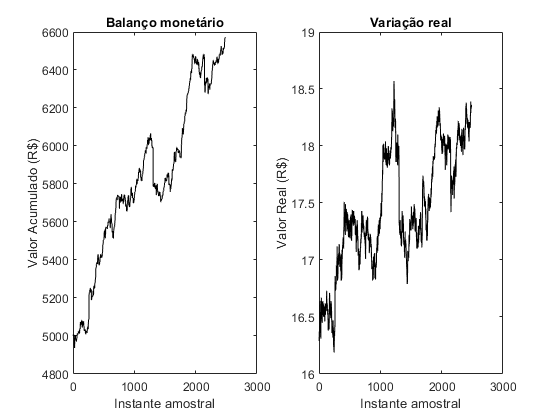

    if expectedReturn > 0
        if ~isBought
            lastPrice = yTest(i);
            isBought = true;
            qtdOperations = qtdOperations + 1;
        end
    else
        if isBought
            money = (money * yTest(i)) / lastPrice;
            isBought = false;
        end
    end
    moneyHistoric = [moneyHistoric money];
end

clf; figure(4); subplot(1,2,1);
plot(moneyHistoric, '-k'); title("Balanço monetário");
xlabel("Instante amostral");
ylabel("Valor Acumulado (R$)");

subplot(1,2,2);
plot(yTest, '-k'); title("Variação real");
xlabel("Instante amostral");
ylabel("Valor Real (R$)")

#### Functions

Triângulo complementar (função de pertinência das entradas)

function res = triComp(funcDefPos)
    res = cell(1, funcDefPos(1));
    center = funcDefPos(2);
    space = (funcDefPos(3) - funcDefPos(2)) / (funcDefPos(1)-1);
    for i=1:1:funcDefPos(1)
        res(i) = {@(x)triangle(x,center-space, center, center+space)};
        center = center + space;
    end
end

Definição da função triangular

function res = triangle(x,a,m,b)
    res = max(min((x-a)/(m-a), (b-x)/(b-m)), 0);
end

Define um neurônio e sua determinada saída

function res = neuron(per, w)
    res = sum(per.*w) / sum(per);
end

Executa o modelo e retorna um valor

function res = NFN(x, w, funcs, funcDef)
    pertinence  = linspace(0, 0, sum(funcDef(:,1)));
    outs        = linspace(0, 0, length(x)); 
    cont        = 1; 
    
    for j = 1:1:length(x)                            % Passa por todas as entradas da amostra
        start = cont;  
        for k = 1:1:funcDef(j,1)                     % Verifica a entrada em cada função
            pertinence(cont) = funcs{cont}(x(j));
            cont = cont+1;
        end
        outs(j) = neuron(pertinence(start:cont-1), w(start:cont-1));
    end
    res = sum(outs);
end